clc;
clear;
close all;
%% 三个初始构型运动过程中的可操作度对比
% 三个初始构型分别是关节优化范围内的构型1，与构型1具有相同末端位姿的位于优化范围外的构型2，位于关节优化范围的随机构型3


% 五次多项式求解
T_all = 15;      % 运动总时间
t_int = 0.002;  % 采样间隔
d_dul = 0.3;    % 运动距离，注意区别正反向

a3 = 10/(T_all^3);
a4 = -15/(T_all^4);
a5 = 6/(T_all^5);
t_sam = 0:t_int:T_all;
v_sca = 3*a3 * t_sam.^2 + 4*a4 * t_sam.^3 + 5*a5 * t_sam.^4;
v_pos = d_dul * v_sca;
v_neg = - d_dul * v_sca;

% 定义末端速度
num_vel = size(v_pos,2);        % 速度节点数量
v_xpos = zeros(6,num_vel);
v_xpos(1,:) = v_pos;
v_xneg = zeros(6,num_vel);
v_xneg(1,:) = v_neg;
v_ypos = zeros(6,num_vel);
v_ypos(2,:) = v_pos;
v_yneg = zeros(6,num_vel);
v_yneg(2,:) = v_neg;
v_zpos = zeros(6,num_vel);
v_zpos(3,:) = v_pos;
v_zneg = zeros(6,num_vel);
v_zneg(3,:) = v_neg;

% Confi_Opti = [46.292860164671566; -88.50; -32.830923535304436; 69.082089651126765; 33.890659060671055; -85.886442035153777; 42.444972545272080];     % 优化构型1
Confi_Opti = [46.028077757746665; -86.50; -32.201453838896192; 69.322789349405184; 32.917863176637965; -86.816319958937925; 44.238963103381131];
% Confi_OutOpti = [143.6971574114474; 24.00; -69.3535260543474; -44.5615875940660; 97.9820912575147; -132.9894691309734; 122.5620376277255];
% Confi_OutOpti = [138.5051485692268; 24.50; -64.6051678816212; -19.6906061872884; -105.0342345610541; 133.9433100102033; -54.7221341795219];
Confi_OutOpti = [120.0924773068039; 167; 36.5343861490611; 35.3315781098094; 97.4317608097554; -83.0799536585081; -53.1704697041120];

Confi_Rand = [100; 40; 70; -50; 130; 120; 10];
All_Confi = [Confi_Opti, Confi_OutOpti, Confi_Rand];
Mani_Confi = zeros(num_vel,3);
norm_Confi = zeros(num_vel,3);

for ii = 1:3
    Confi_Deg = All_Confi(:,ii);
    theta_Orientation = Confi_Deg * pi / 180;       % 定义机械臂初始构型    % ini_confi*pi/180      % 单位转化，将°转化为rad
    angle_alljoint = zeros(7,num_vel);      % 记录各关节角的中间变量，用于绘制角度变化曲线
    vel_theta = zeros(7,num_vel);         % 各关节角速度，用于绘制角速度变化曲线
    v_allend = zeros(6,num_vel);          % 根据得到的角速度计算末端速度，用于验证误差
    ang_dedai = zeros(7,num_vel);         % 记录每个采样周期内的角度变化量
    angle_alljoint(:,1) = theta_Orientation;

    for jj = 1:num_vel
        Theta_update = angle_alljoint(:,jj);
        matrix_jacobi = JoiAngToJacMatBase(Theta_update);
        matrix_zhuanzhi = matrix_jacobi.';
        matrix_ladder = matrix_jacobi * matrix_zhuanzhi;      % inv(matrix_jacobi*matrix_zhuanzhi);
        jacobi_inv = matrix_zhuanzhi / matrix_ladder;
        v_joint = jacobi_inv * v_yneg(:,jj);      %计算关节速度v_joint
        vel_theta(:,jj) = v_joint;                  % 记录关节角速度，绘制图像
        v_allend(:,jj) = matrix_jacobi * v_joint;    % 根据求出的关节速度计算末端速度进行验证

        ang_dedai(:,jj) = vel_theta(:,jj) * t_int;      % 每个采样周期内的角度变化量
        angle_alljoint(:,jj+1) = angle_alljoint(:,jj) + ang_dedai(:,jj);
    end
    angle_alljoint(:,num_vel+1) = [];         % 去除关节角度中多余的一列

    for kk= 1:num_vel
        %     Theta_degree = conf_opti(ii,:);
        Theta_rad = angle_alljoint(:,kk);            % Theta_degree * pi / 180;
        Jaco_Base = JoiAngToJacMatBase(Theta_rad);
        Trans_JacoBase = Jaco_Base.';
        det_JacoBase = det(Jaco_Base * Trans_JacoBase);
        Mani_Confi(kk,ii) = sqrt(det_JacoBase);
        norm_Confi(kk,ii) = Mani_Confi(kk,ii) / 30;       % 可操作度归一化
    end
end


figure('Name','Manipulability');
plot(t_sam, Mani_Confi(:,1),'-*','MarkerIndices',1:300:length(t_sam));
hold on;
plot(t_sam, Mani_Confi(:,2),'-^','MarkerIndices',1:300:length(t_sam));
% plot(t_sam, Mani_Confi(:,3),'-o','MarkerIndices',1:300:length(t_sam));
xlabel('Time/(s)');
ylabel('Manipulability');
legend('Optimized Configuration','Random Configuration 1','Random Configuration 2','Location','best');

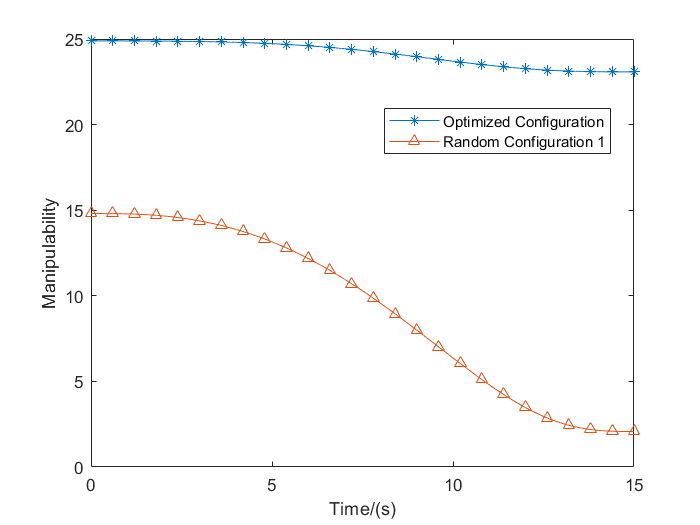

hold off;

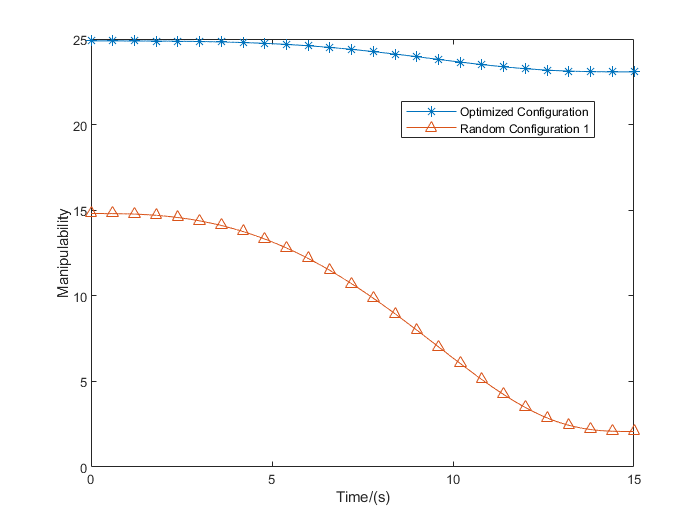


figure('position',[100 300 273 220],'Name','Normalized Manipulability');        % [100 100 260 220]
plot(t_sam, norm_Confi(:,1),'-*','LineWidth',1,'MarkerIndices',1:500:length(t_sam));
hold on;
plot(t_sam, norm_Confi(:,2),'-^','LineWidth',1,'MarkerIndices',1:500:length(t_sam));
% plot(t_sam, norm_Confi(:,3),'-o','MarkerIndices',1:300:length(t_sam));
set(gca,'Position',[0.15 0.17 0.80 0.74]);
ylim([0 0.85]);
xlabel('Time/(s)');
ylabel('Normalized manipulability');
figure_FontSize=8;
set(get(gca,'XLabel'),'FontSize',figure_FontSize,'Vertical','middle');
set(get(gca,'YLabel'),'FontSize',figure_FontSize,'Vertical','baseline');
set(findobj('FontSize',10),'FontSize',figure_FontSize);

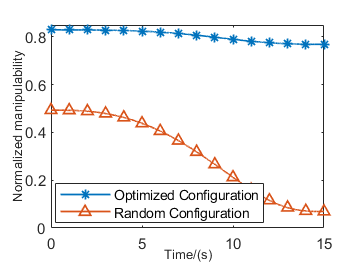

set(findobj(get(gca,'Children'),'LineWidth',0.5),'LineWidth',1);
% legend('Optimized Configuration','Random Configuration','Random Configuration 2','Location','best');
legend('Optimized Configuration','Random Configuration','Location','best');
hold off;


% 求解优选构型的相对可操作度的平均值和最大最小值
Opti_RelaMeanVal = mean(norm_Confi(:,1))

Opti_RelaMeanVal =    0.804470989281967


[Min_OptiRelaMani, Max_OptiRelaMani] = bounds(norm_Confi(:,1))

Min_OptiRelaMani =    0.769284031179279


Max_OptiRelaMani =    0.829604562501449


% 求解随机构型的相对可操作度的平均值和最大最小值
Ran_RelaMeanVal = mean(norm_Confi(:,2))

Ran_RelaMeanVal =    0.309657374739577


[Min_RanRelaMani, Max_RanRelaMani] = bounds(norm_Confi(:,2))

Min_RanRelaMani =    0.069117980009298


Max_RanRelaMani =    0.493490428464640



ConfiVar = [39.4775 20.5113;            % 每个初始构型沿六个方向运动后的最大构型变化量和z轴方向的构型变化量
            102.7063 24.5898;
            41.0230 30.6160];
Rela_ConfiVar = zeros(3,1);
for ii = 1:3
    Rela_ConfiVar(ii) = 1.8 * exp(-0.03 * ConfiVar(ii,1));
end

OptiTar = zeros(3,1);
for ii = 1:3
    OptiTar(ii) = 0.7 * norm_Confi(1,ii) + 0.3 * Rela_ConfiVar(ii);
end

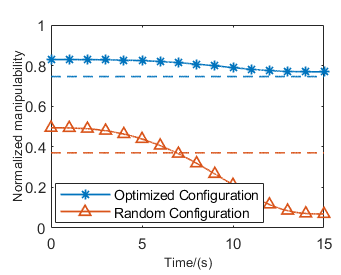

Opti_RelaVari = zeros(num_vel,1);
Opti_RelaVari(:,1) = OptiTar(1);
Ran_RelaVari = zeros(num_vel,1);
Ran_RelaVari(:,1) = OptiTar(2);

figure('position',[100 300 273 220],'Name','Normalized Manipulability');        % [100 100 260 220]
plot(t_sam, norm_Confi(:,1),'-*','Color',[0.00,0.45,0.74],'LineWidth',1,'MarkerIndices',1:500:length(t_sam));
hold on;
plot(t_sam, norm_Confi(:,2),'-^','Color',[0.85,0.33,0.10],'LineWidth',1,'MarkerIndices',1:500:length(t_sam));
plot(t_sam,Opti_RelaVari,'--','Color',[0.00,0.45,0.74],'LineWidth',1,'MarkerIndices',1:500:length(t_sam))
plot(t_sam, Ran_RelaVari,'--','Color',[0.85,0.33,0.10],'LineWidth',1,'MarkerIndices',1:500:length(t_sam));

% plot(t_sam, norm_Confi(:,3),'-o','MarkerIndices',1:300:length(t_sam));
set(gca,'Position',[0.15 0.17 0.80 0.74]);
xlabel('Time/(s)');
ylabel('Normalized manipulability');
figure_FontSize=8;
set(get(gca,'XLabel'),'FontSize',figure_FontSize,'Vertical','top');
set(get(gca,'YLabel'),'FontSize',figure_FontSize,'Vertical','baseline');
set(findobj('FontSize',10),'FontSize',figure_FontSize);
set(findobj(get(gca,'Children'),'LineWidth',0.5),'LineWidth',1);
% legend('Optimized Configuration','Random Configuration','Random Configuration 2','Location','best');
legend('Optimized Configuration','Random Configuration','Location','best');
hold off;

function [Jaco_base] = JoiAngToJacMatBase(Theta_rad)
%% 计算以基坐标系为参考的雅可比矩阵
%   输入量为包含7个关节角度的数组，单位为弧度rad；
%   输出量为使用旋量法以基坐标系为参考的雅可比矩阵
%% 机械臂关节常量定义





%% 关节角度赋值
theta1 = Theta_rad(1);
theta2 = Theta_rad(2);
theta3 = Theta_rad(3);
theta4 = Theta_rad(4);
theta5 = Theta_rad(5);
theta6 = Theta_rad(6);
theta7 = Theta_rad(7);
%% 求解公式
JB_S1 = [-1;
          0;
          0;
          0;
          0;
          0];
JB_S2 = [0;
         -sin(theta1);
         -cos(theta1);
         0;
         -a0N*cos(theta1);
         a0N*sin(theta1)];
JB_S3 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         a1N*sin(theta2);
         a1N*cos(theta1)*cos(theta2) - a0N*cos(theta2)*sin(theta1)*sin(theta2) + a0N*sin(theta1)*sin(theta2)*(cos(theta2) - 1);
         a0N*cos(theta1)*sin(theta2)*(cos(theta2) - 1) - a0N*cos(theta1)*cos(theta2)*sin(theta2) - a1N*cos(theta2)*sin(theta1)];
JB_S4 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         cos(theta3)*sin(theta2)*(a1N + a3N) - cos(theta1)*sin(theta2)*(a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta1)*sin(theta2)*(a1N*sin(theta1)*(cos(theta3) - 1) - a0N*cos(theta1)*sin(theta2) + a1N*cos(theta1)*cos(theta2)*sin(theta3));
         sin(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3)) - (a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) - cos(theta2)*(a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         cos(theta2)*(a1N*sin(theta1)*(cos(theta3) - 1) - a0N*cos(theta1)*sin(theta2) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + cos(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3))];
JB_S5 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         - (sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta1)*sin(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + a1N*cos(theta1)*cos(theta2)*sin(theta3));
         sin(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) - (cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - cos(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         cos(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + cos(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1))];
JB_S6 = [sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) - cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3));
         sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) - cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)));
         sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) - cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)));
         (cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - (cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) + (cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N);
         (cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) + (cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - (cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) + (cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N)];
JB_S7 = [- cos(theta2)*cos(theta6) - sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)));
         cos(theta1)*cos(theta6)*sin(theta2) - sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))));
         - sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) - cos(theta6)*sin(theta1)*sin(theta2);
         (cos(theta2)*sin(theta6) - cos(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*(a1N + a3N + a5N + a7N) - (sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) + cos(theta6)*sin(theta1)*sin(theta2))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) + (sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) - cos(theta1)*cos(theta6)*sin(theta2))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) + sin(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) + cos(theta6)*sin(theta1)*sin(theta2))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + cos(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) - (cos(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) + cos(theta1)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) - (cos(theta2)*cos(theta6) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) + sin(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (cos(theta2)*cos(theta6) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) - sin(theta1)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) - (sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) - cos(theta1)*cos(theta6)*sin(theta2))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + cos(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1))];
Jaco_lad = [JB_S1  JB_S2  JB_S3   JB_S4   JB_S5   JB_S6   JB_S7];
Jaco_base = [Jaco_lad(4:6,:);Jaco_lad(1:3,:)];
end